# Main Results 

This file contains the main results discussed in [Section, Paper]. 

#### Pulse Approximation - pi branch


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1       0.0941204                      1.12e+03               1
     1          2       0.0016934       0.446861         0.0492               1
     2          3     9.75539e-05       0.250844           17.4            1.12
     3          4     1.34005e-07      0.0408612           1.07            1.12
     4          5     3.12999e-13     0.00177101        0.00122            1.12
     5          6     3.10825e-24    2.10338e-06       1.85e-08            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

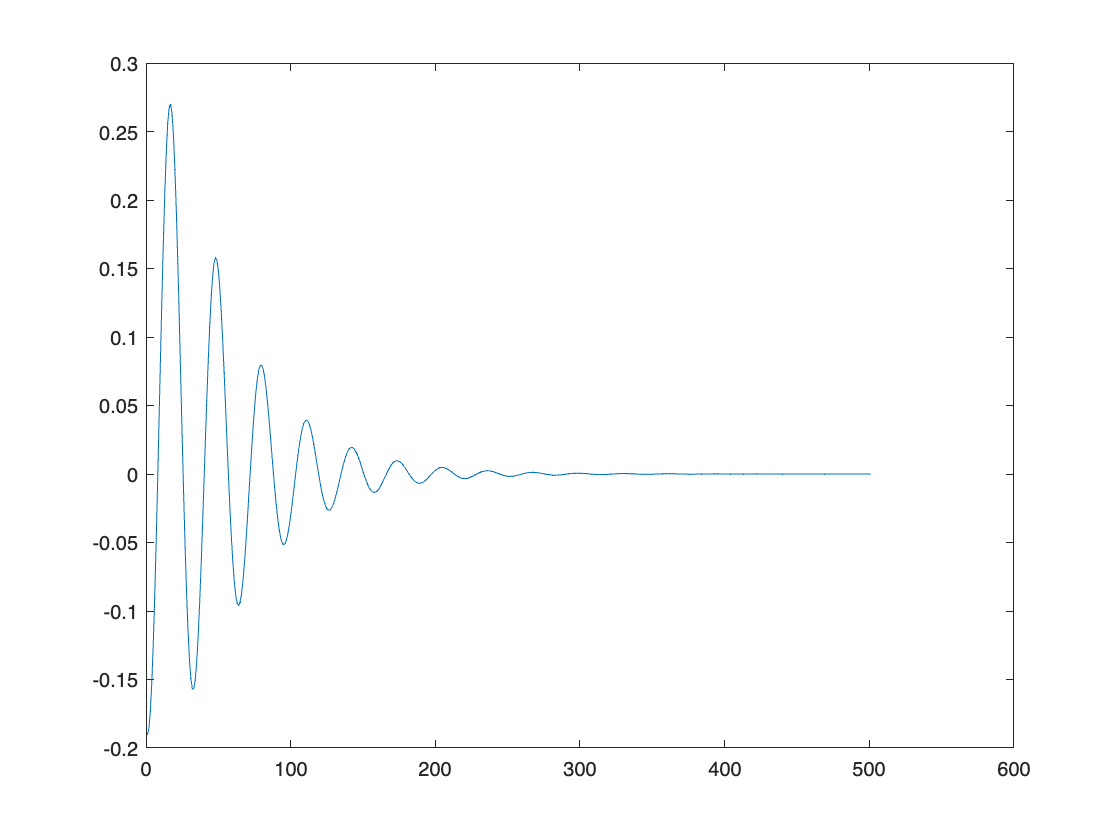

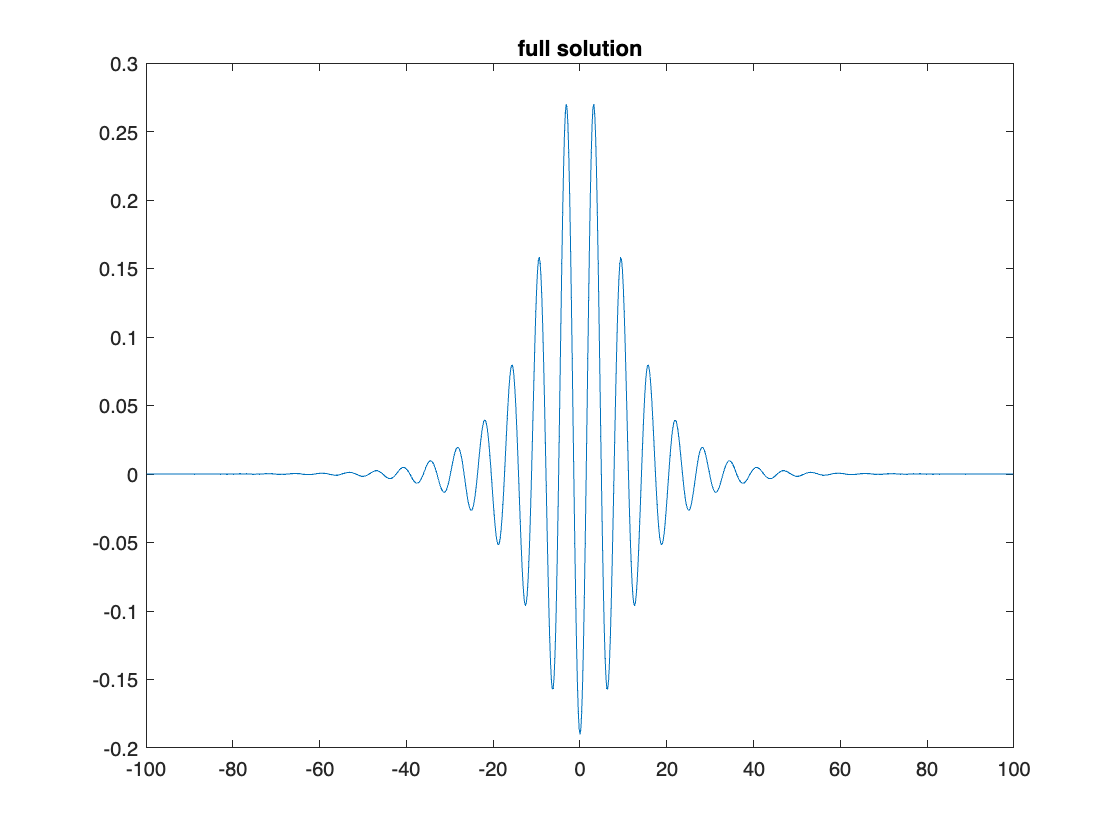

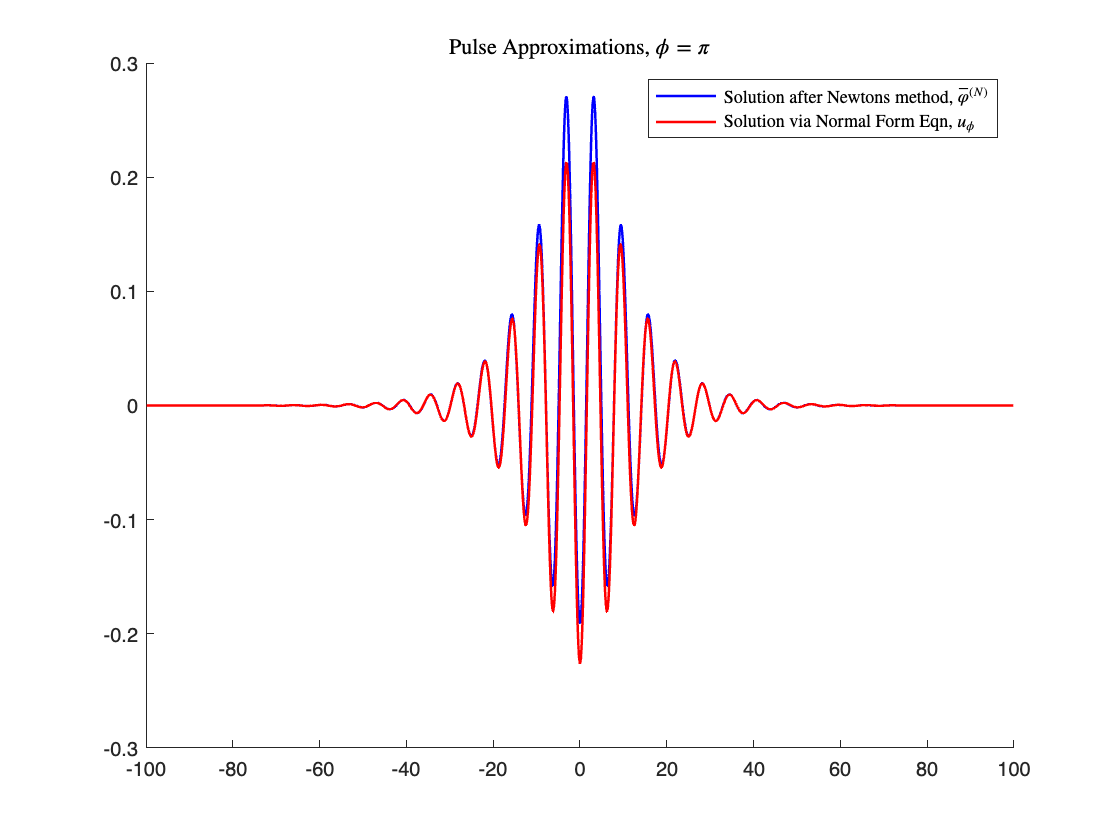

tolerance met
Error:
   3.6912e-13
    0.0058
    0.1179
This subspace is Lagrangian.


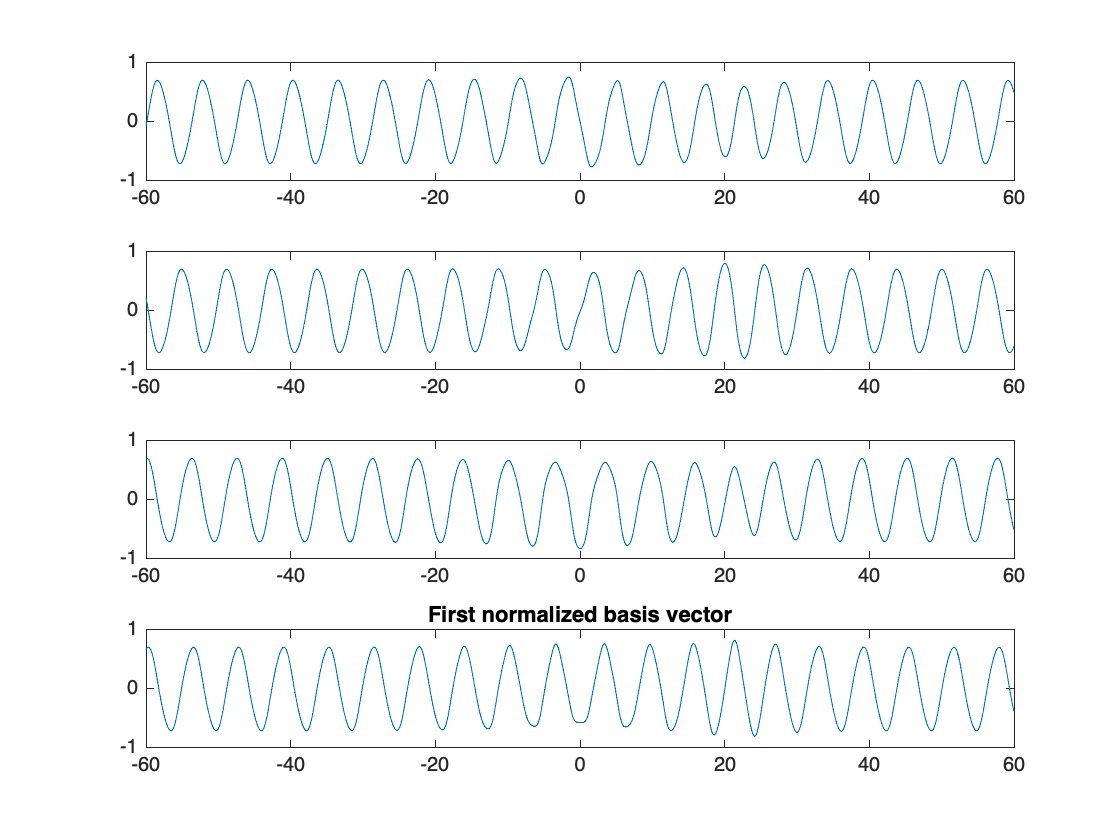

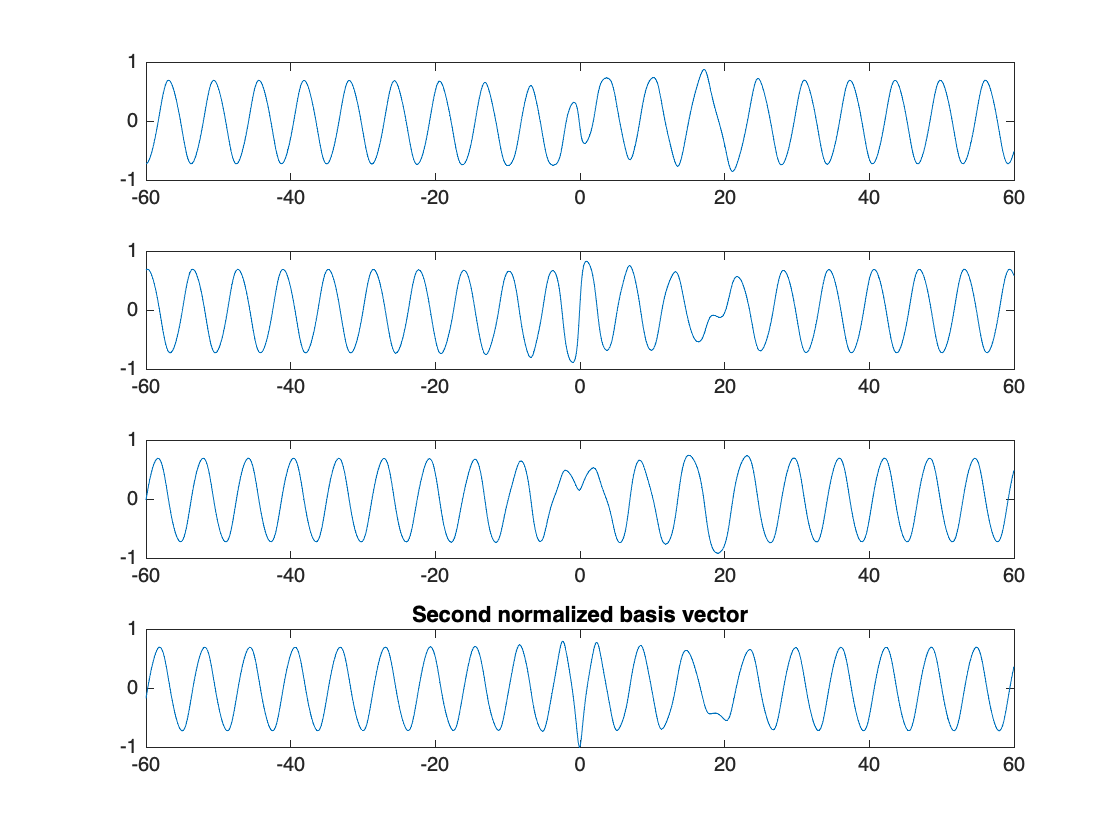

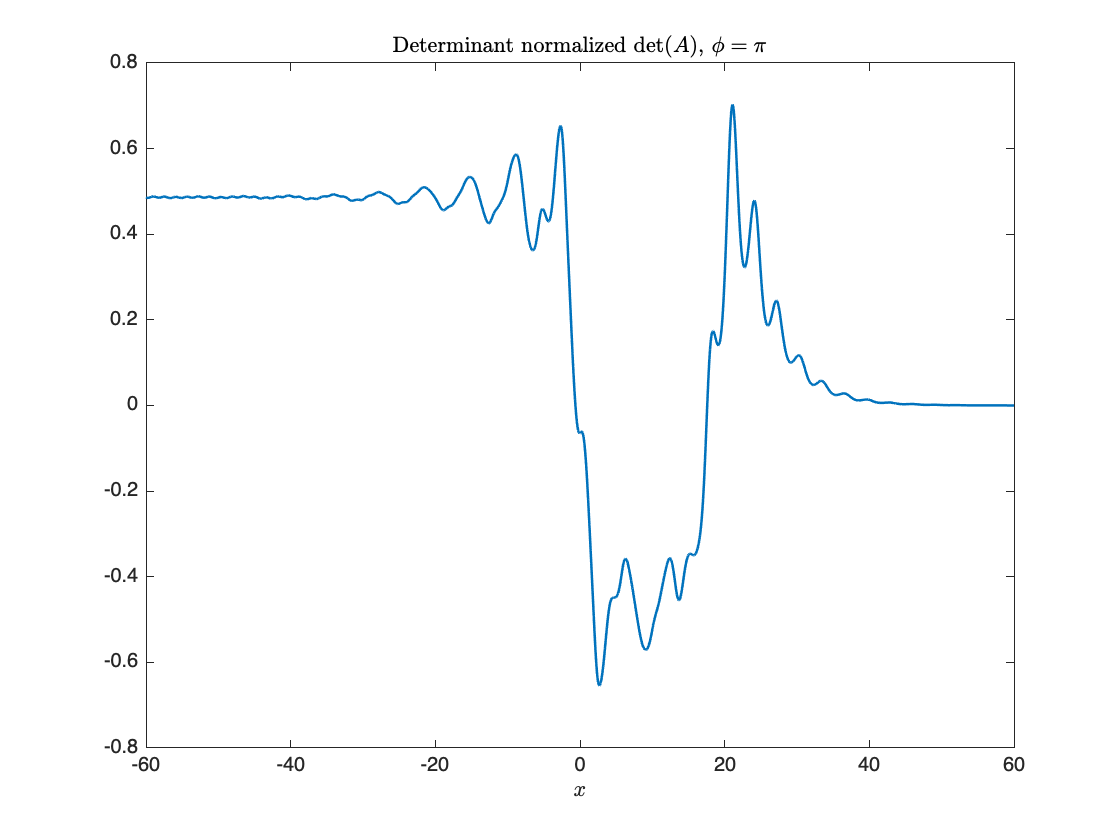

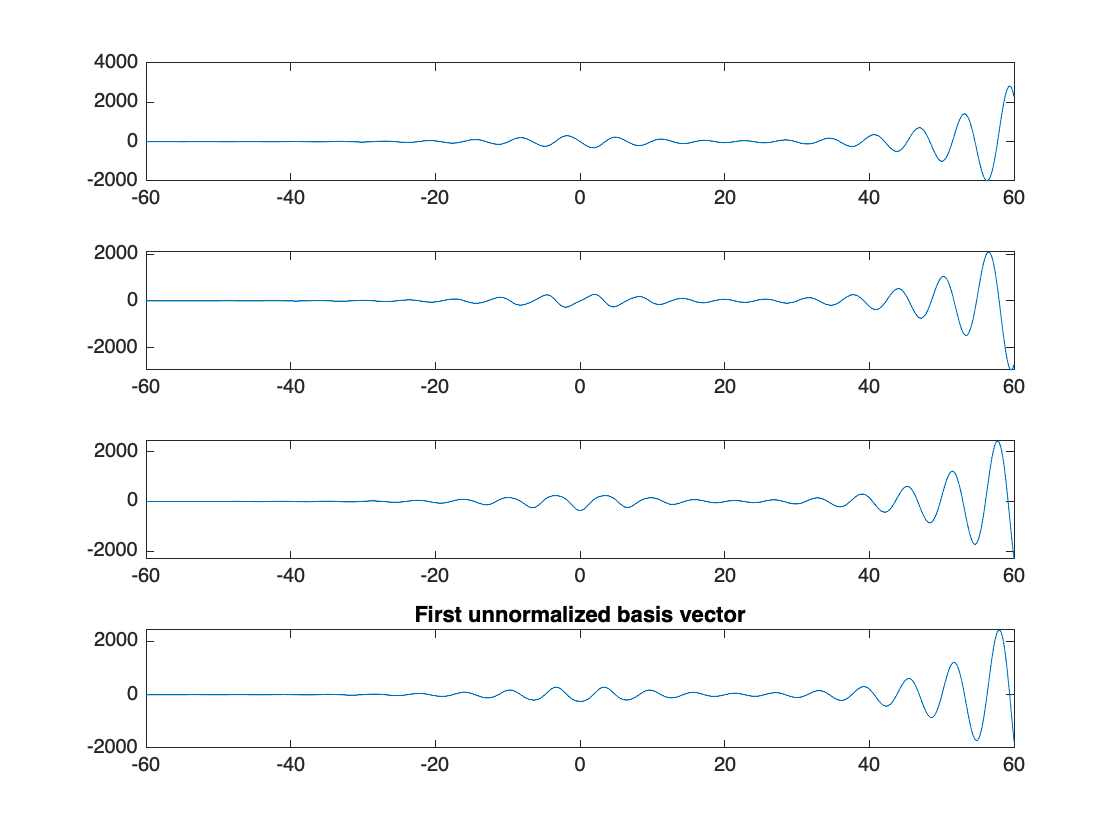

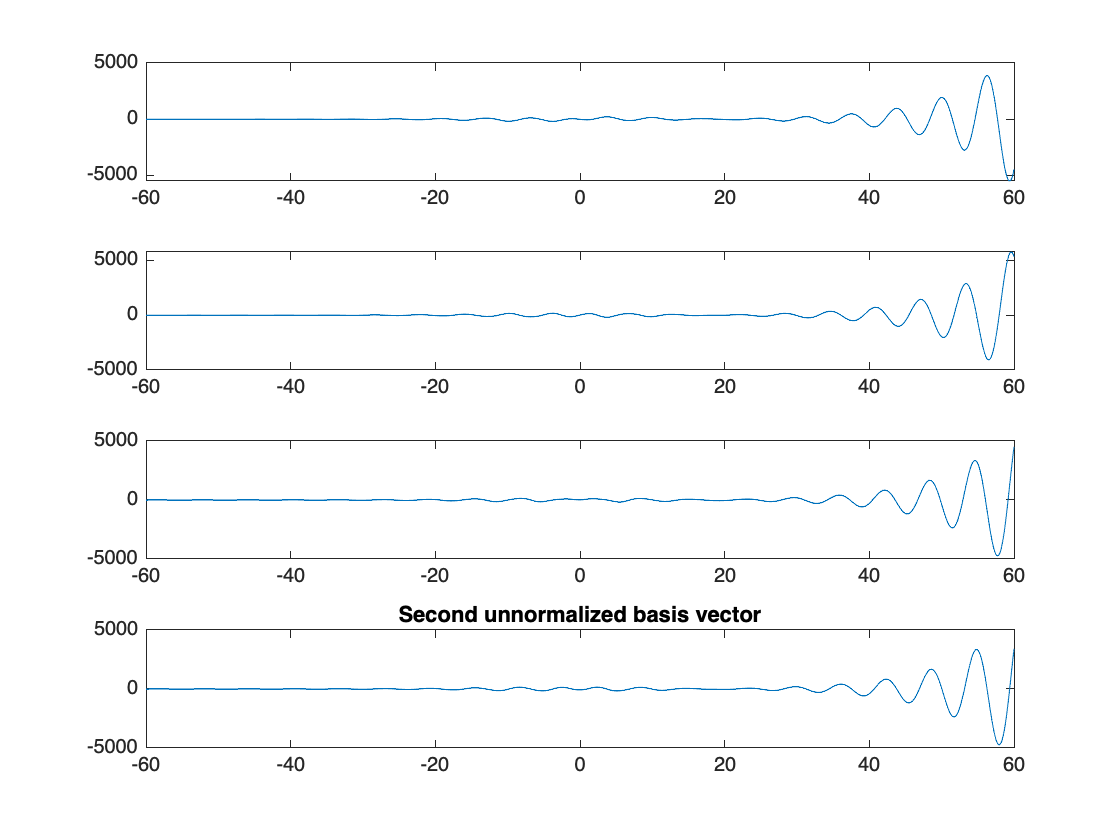

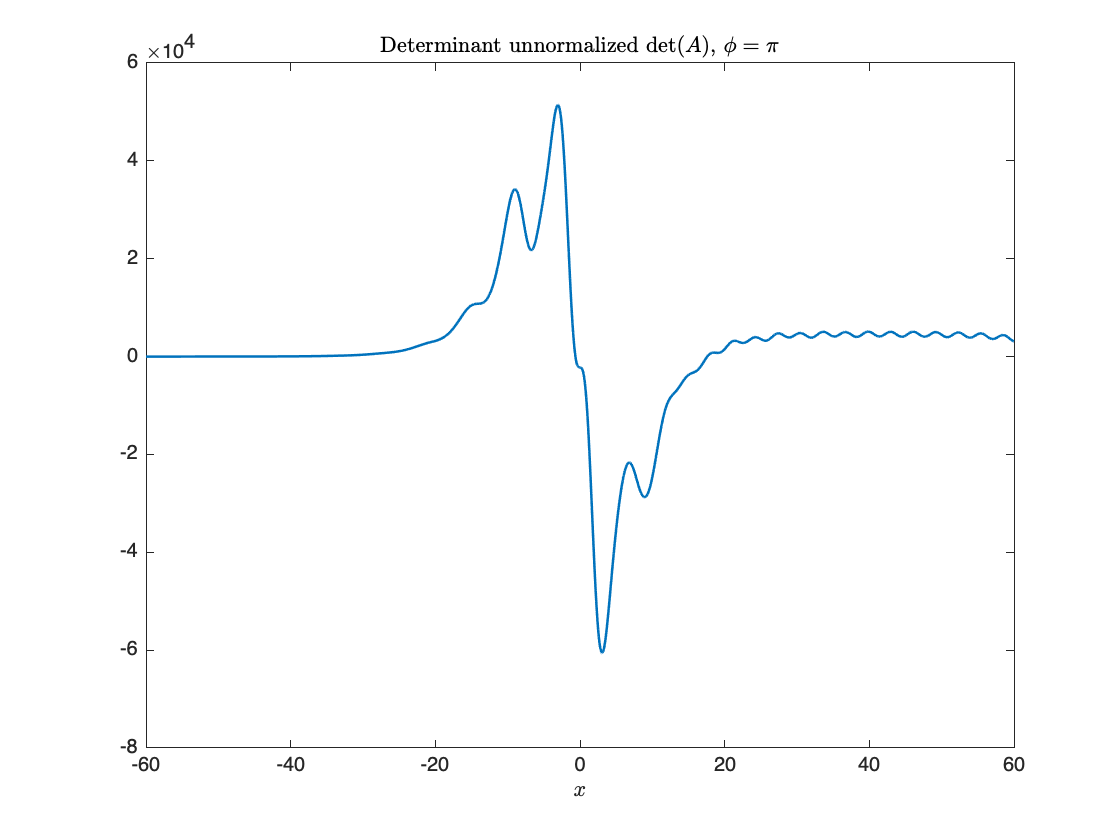

C_pi =   ConjugatePoints with properties:

     conjPts: [1×1 struct]
    vfParams: [1×1 struct]
     Euminus: [1×1 struct]

branch = pi;
C_pi = get_all_plots(branch)

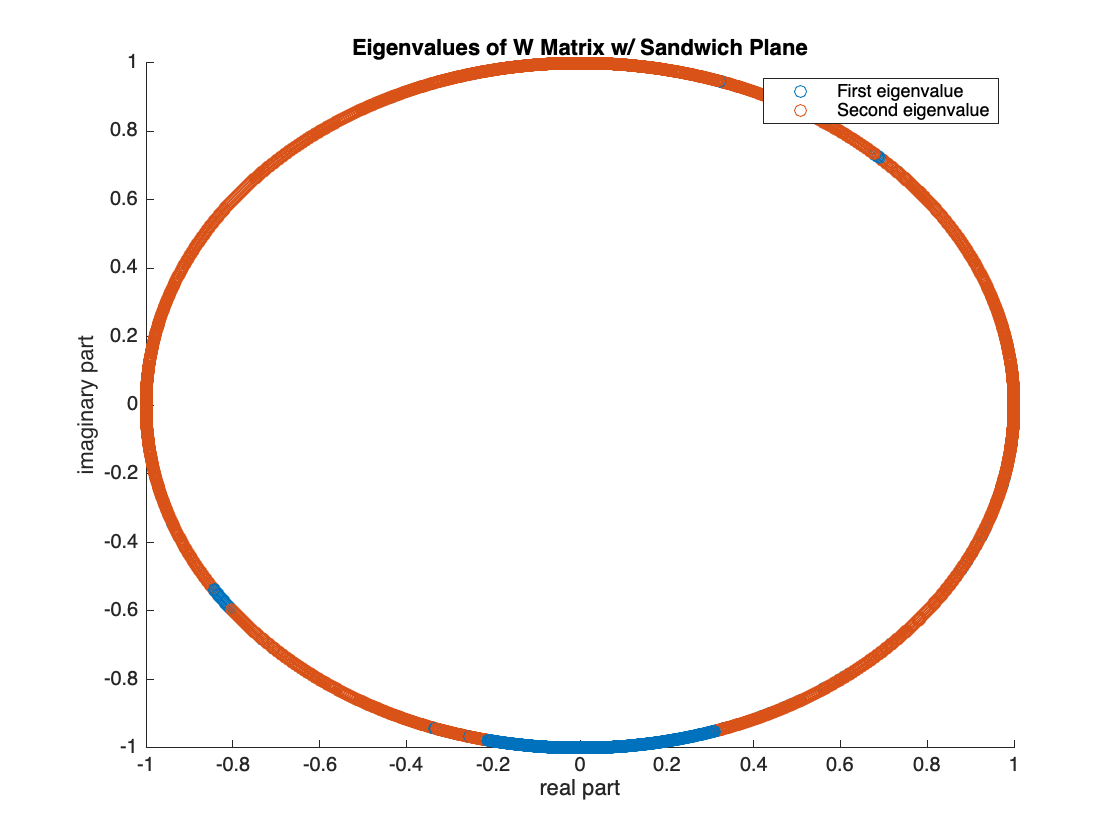

time = C_pi.Euminus.timeVec;
evals_pi = get_W_evals_sandwich_plane(C_pi);

figure
hold on 
plot3(real(evals_pi), imag(evals_pi), time, 'o')
xlabel('real part')
ylabel('imaginary part')
title('Eigenvalues of W Matrix w/ Sandwich Plane')
zlabel('time')
legend('First eigenvalue', 'Second eigenvalue')

#### 0 branch


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1       0.0882328                           459               1
     1          2      0.00177027       0.452275            143               1
     2          3     0.000400908       0.338144            2.3            1.13
     3          4     9.11572e-06       0.140264           8.11            1.13
     4          5     5.59227e-09      0.0185436          0.265            1.13
     5          6     1.31738e-15    0.000447843       1.45e-05            1.13
     6          7     1.46332e-24    2.24371e-07        1.5e-08            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toleran

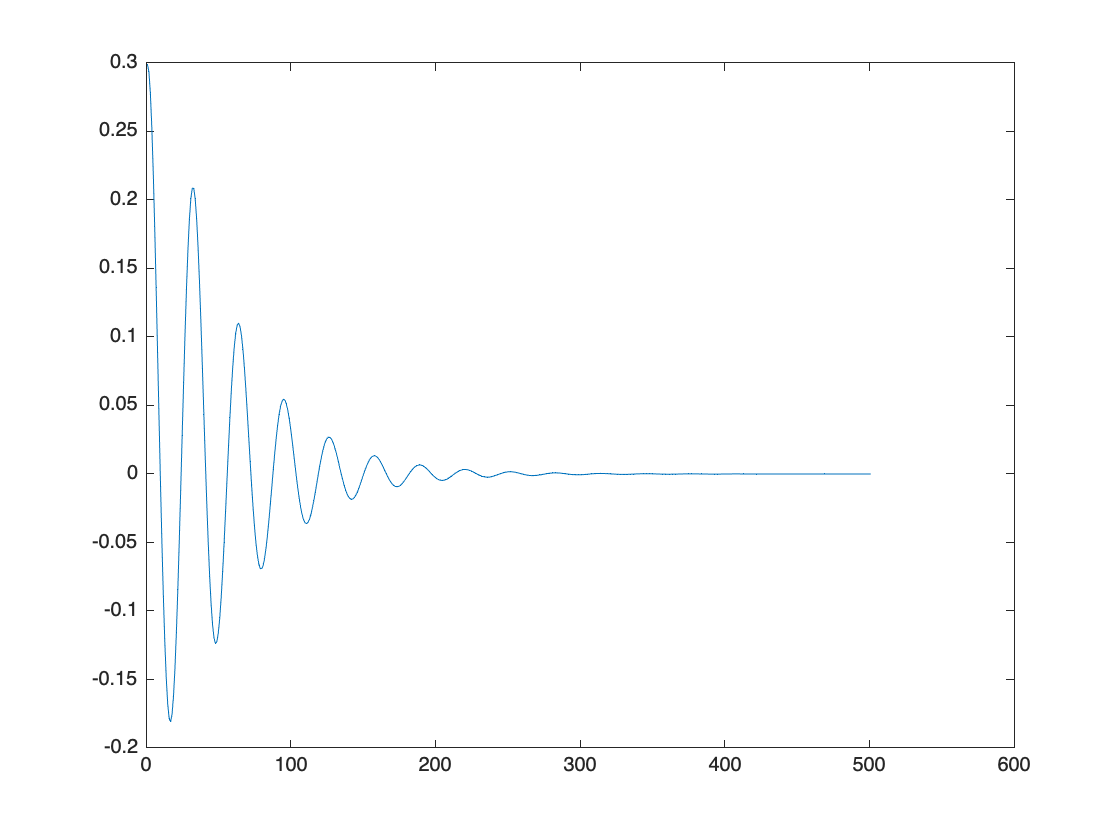

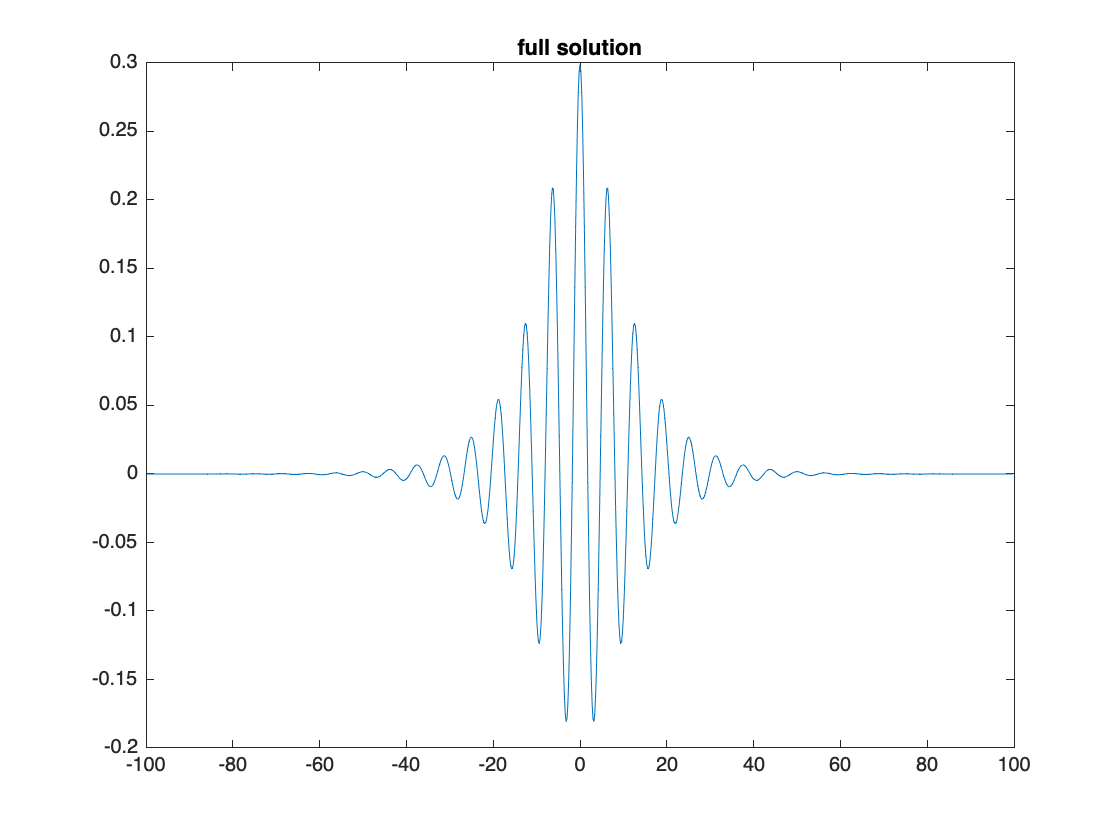

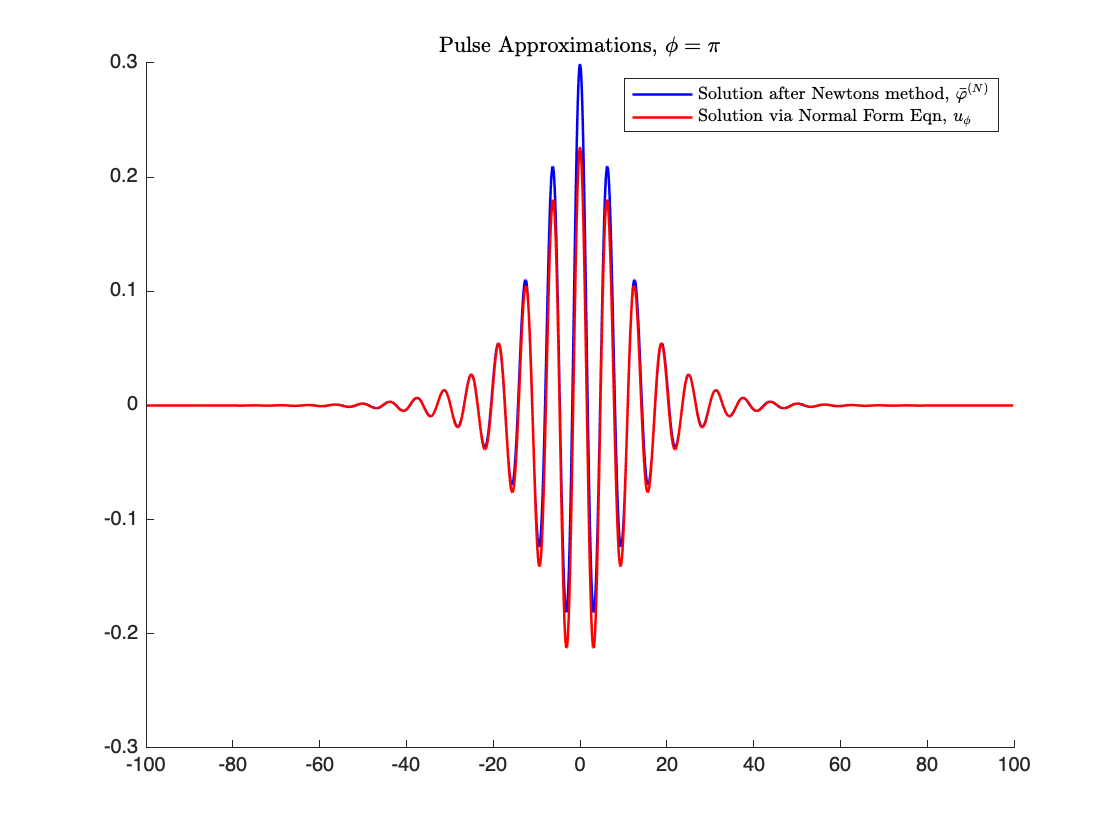

tolerance met
Error:
   1.0174e-11
    0.1209
This subspace is Lagrangian.


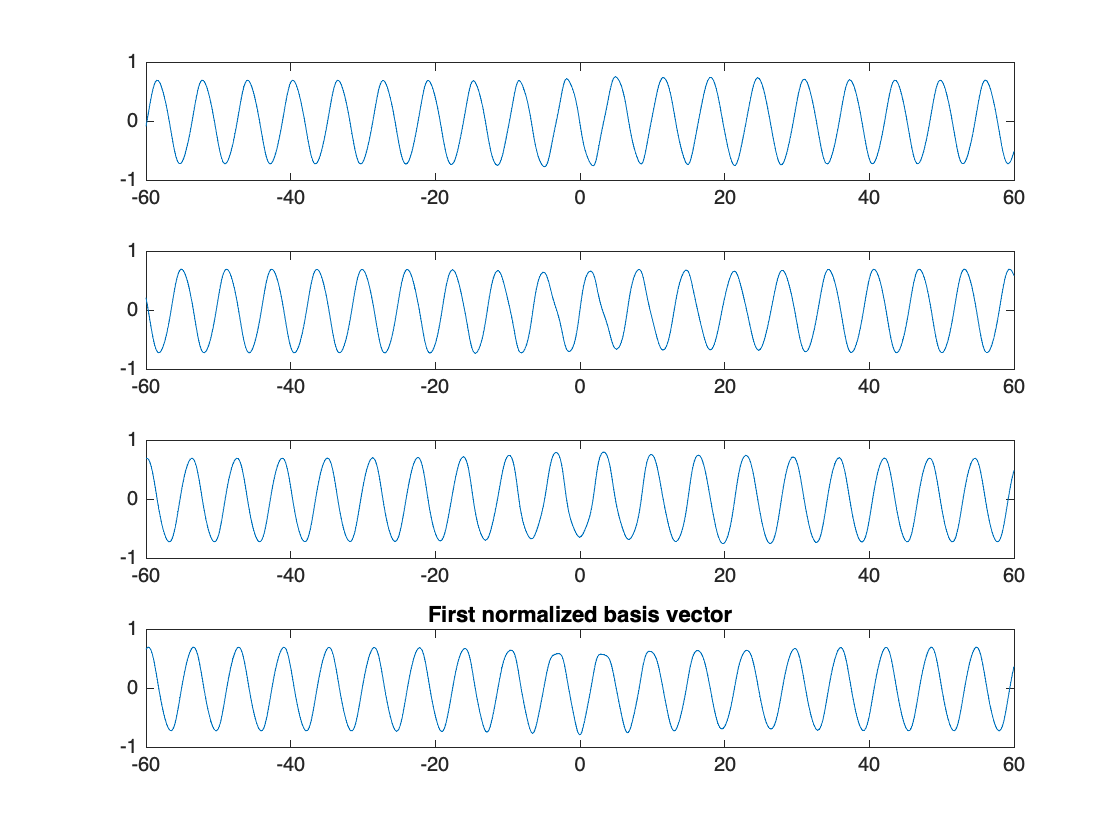

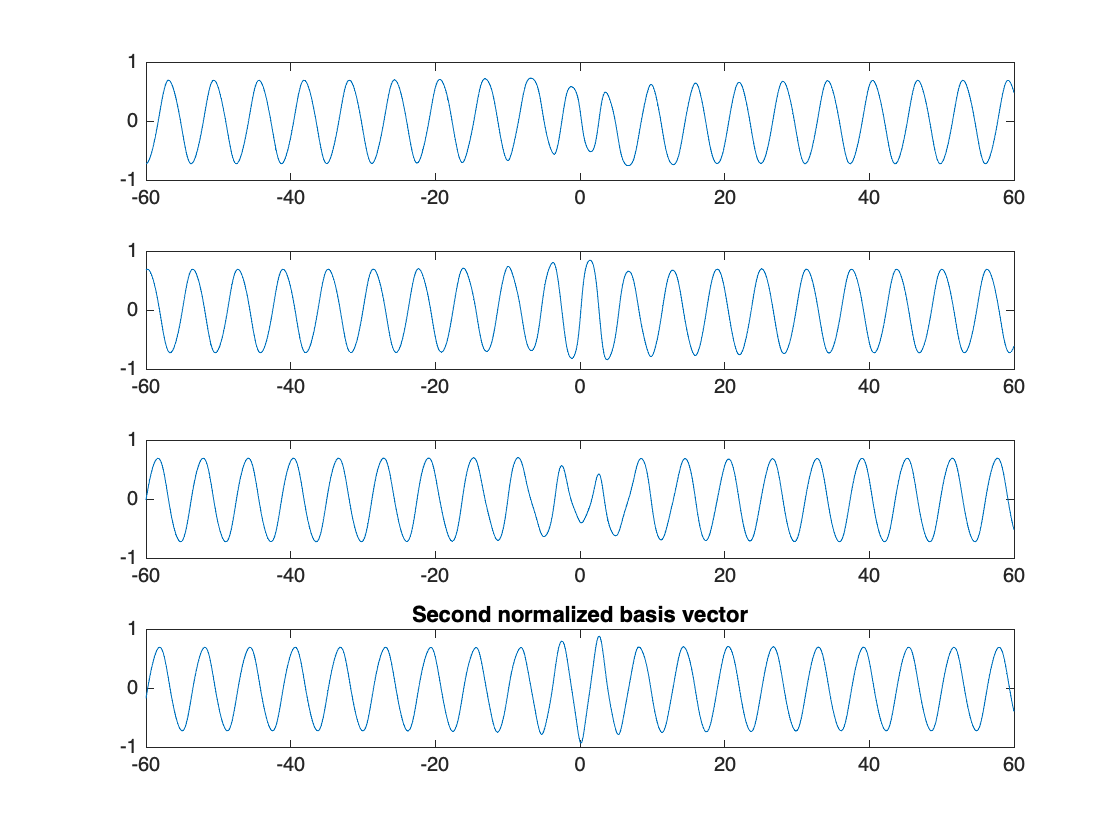

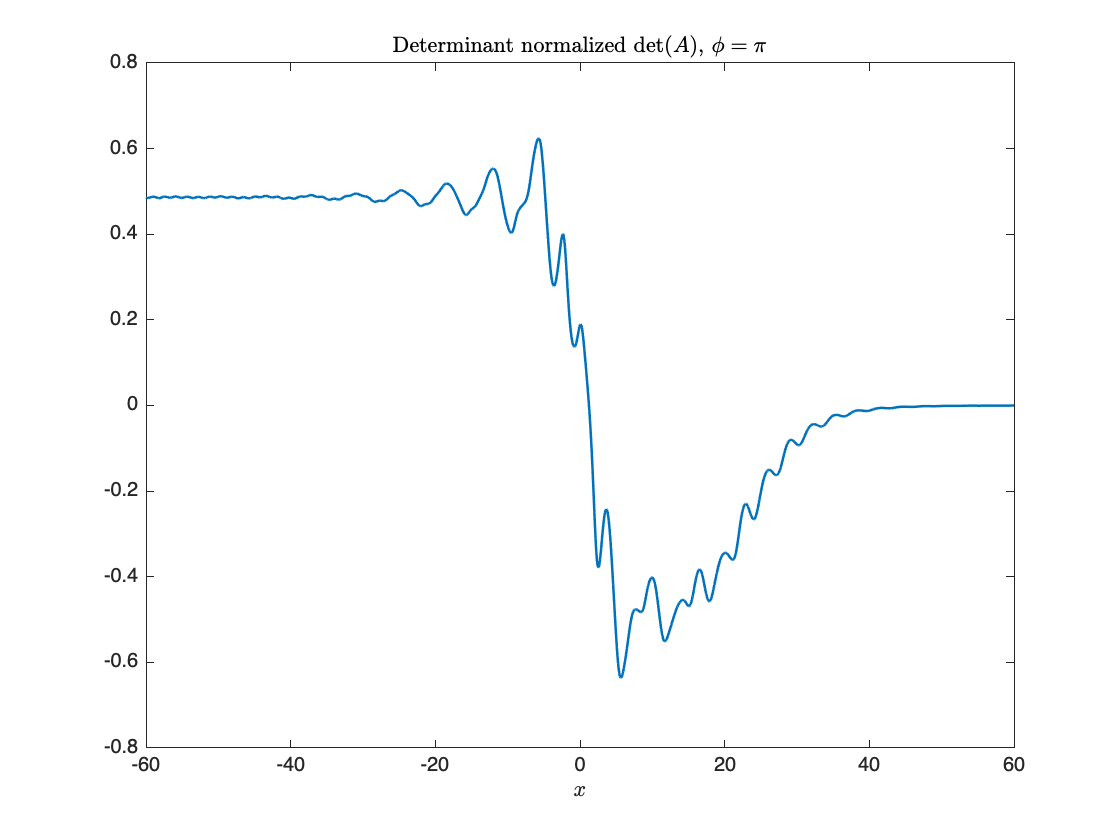

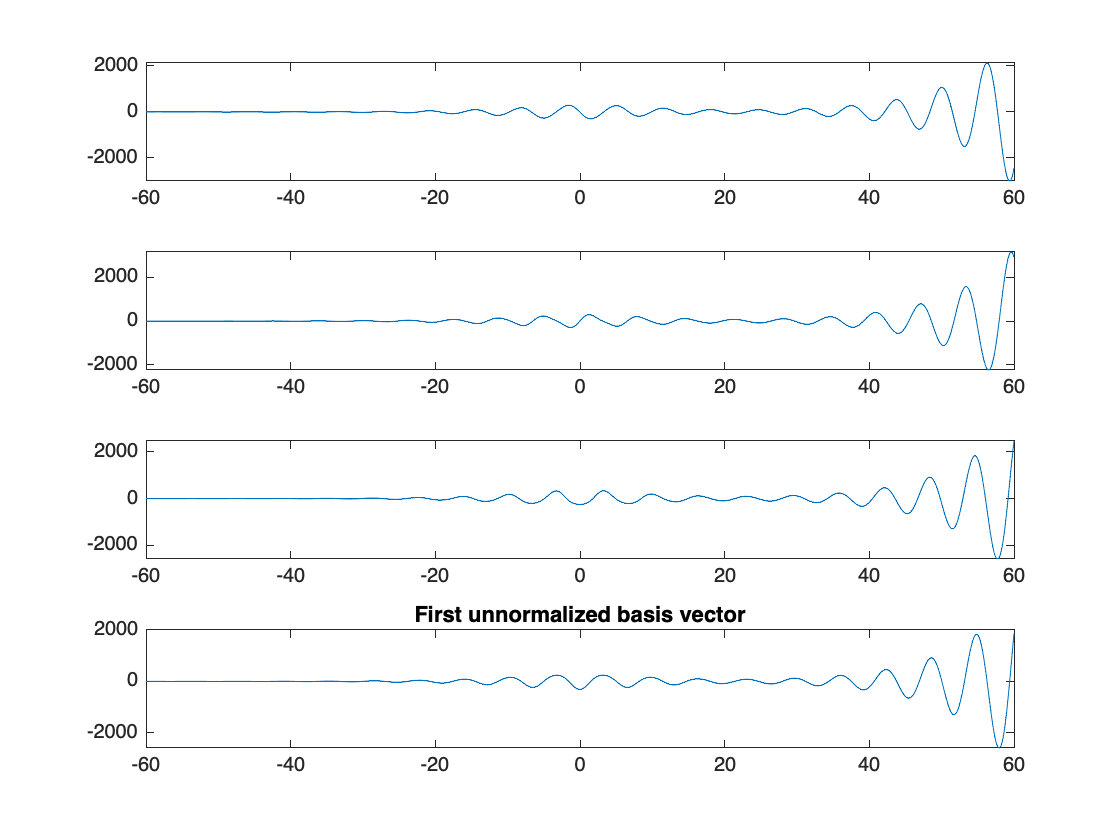

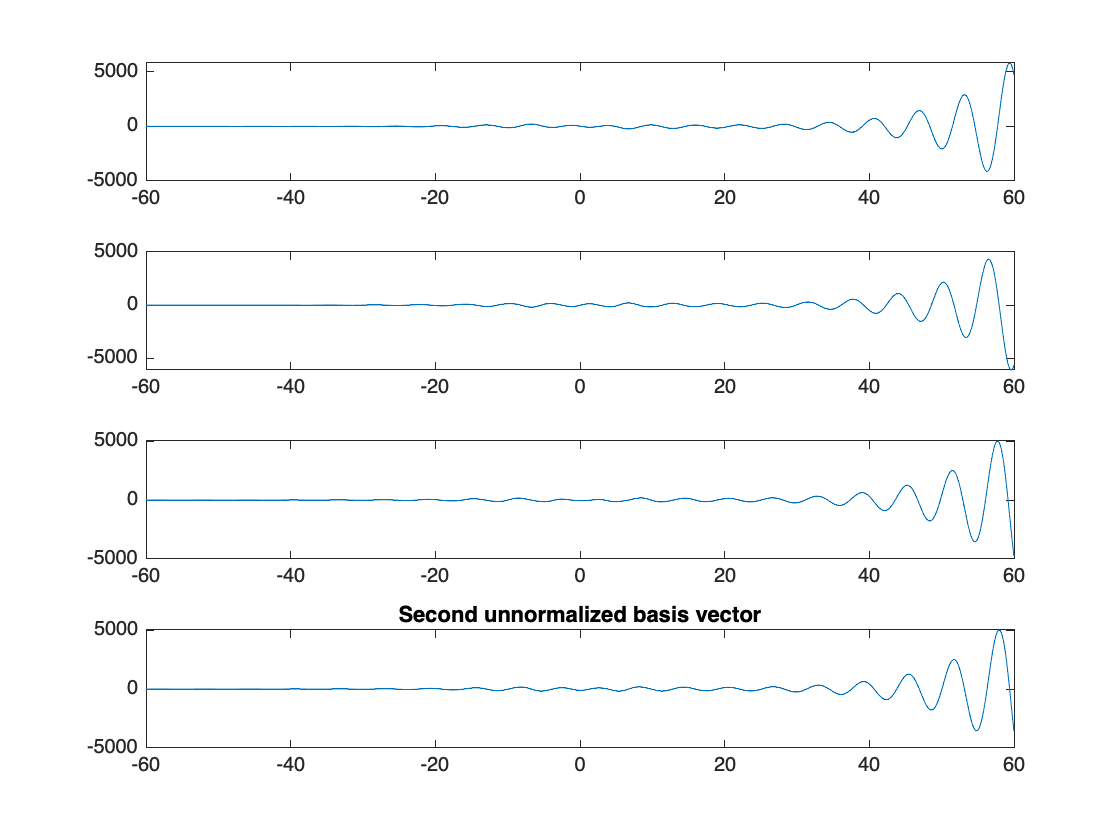

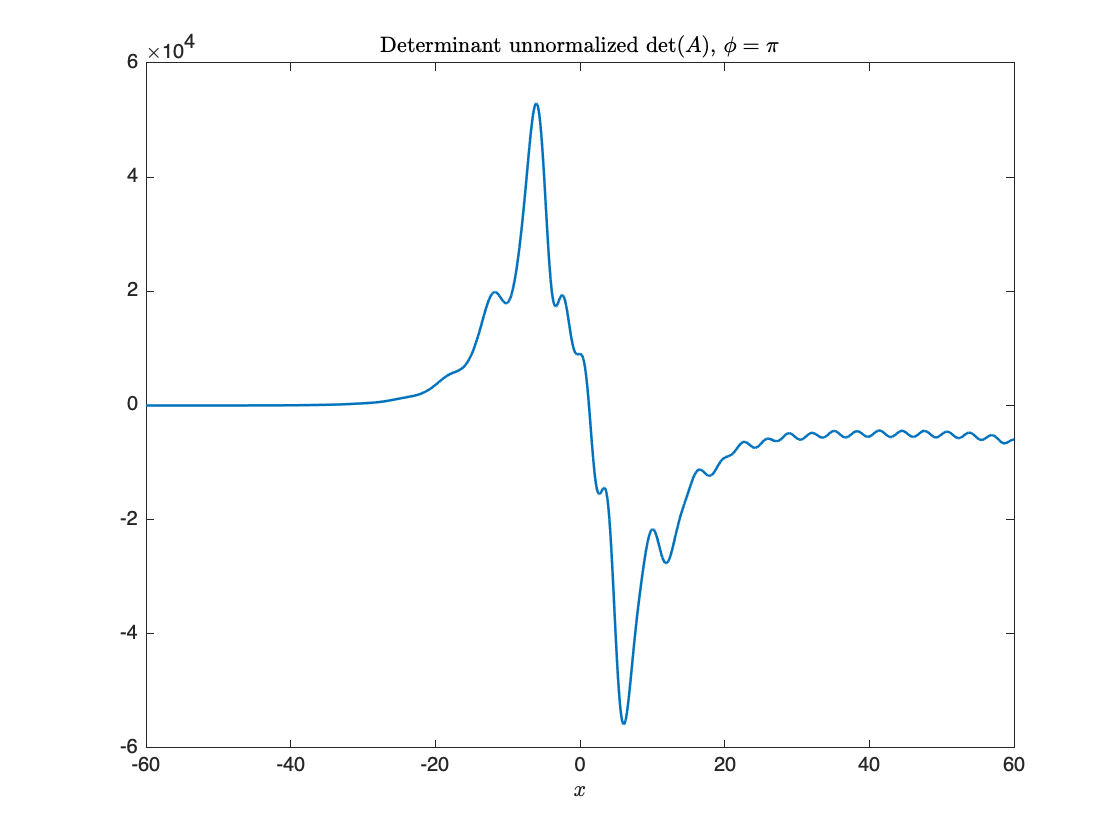

C_0 =   ConjugatePoints with properties:

     conjPts: [1×1 struct]
    vfParams: [1×1 struct]
     Euminus: [1×1 struct]

branch = 0;
C_0 = get_all_plots(branch)

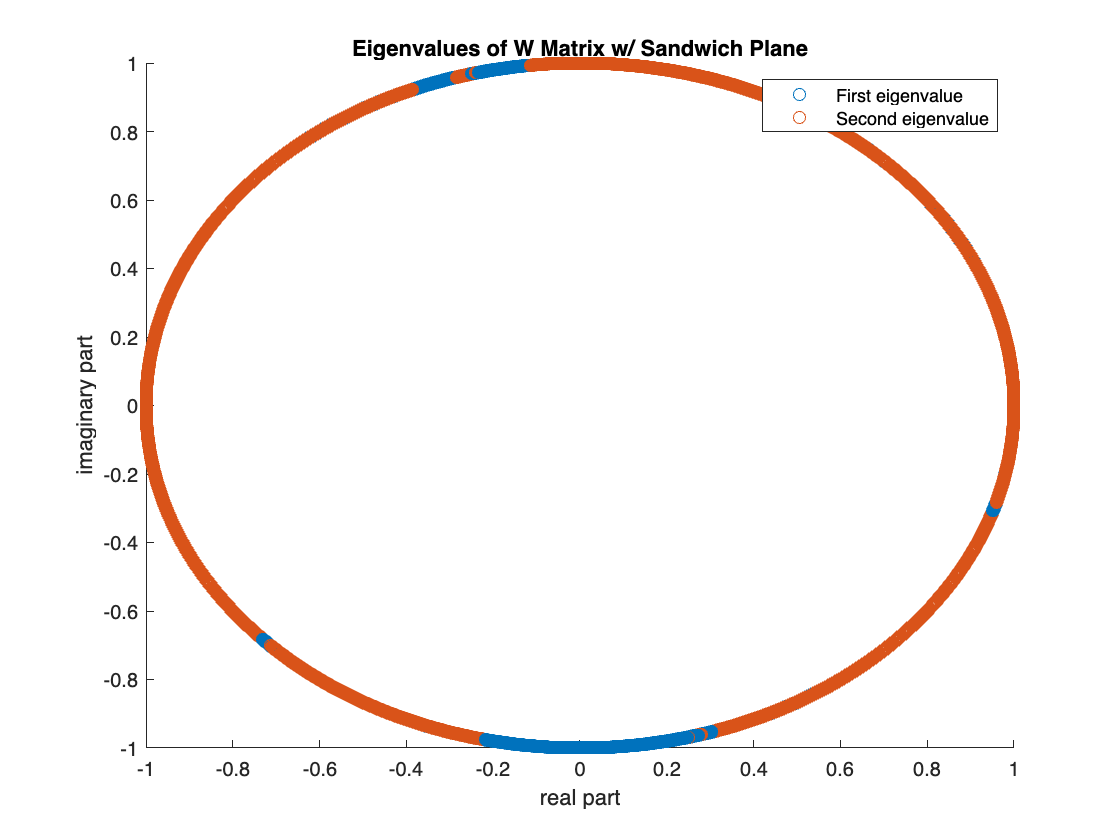

time = C_0.Euminus.timeVec;
evals_0 = get_W_evals_sandwich_plane(C_0);

figure
hold on 
plot3(real(evals_0), imag(evals_0), time, 'o')
xlabel('real part')
ylabel('imaginary part')
title('Eigenvalues of W Matrix w/ Sandwich Plane')
zlabel('time')
legend('First eigenvalue', 'Second eigenvalue')

function evals = get_W_evals_sandwich_plane(C)
    frame = C.Euminus.frame;
    N = max(size(frame));
    evals = zeros(2,N);
    for j = 1:N
        snapshot = frame(:,:,j);
        X = snapshot(1:2,:);
        Y= snapshot(3:4,:);
        X1=[0,0;1,0];
        Y1=[0,1;0,0];
        Wtilde = -(X + 1i*Y)*inv(X-1i*Y)*(X1-1i*Y1)*inv(X1+1i*Y1);
        evals(:,j)=eig(Wtilde); 
    end
end